# ÁTOMO HIDRÓGENO 

## **1. FUNCION DE TIPO GAUSSIANA TRIVIAL** 

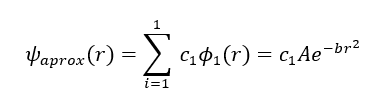

### 1.1 MÉTODO VARIACIONAL CONVENCIONAL (Parámetro  b ajustable, como validación inicial del método)

% Método variacional para el átomo de hidrógeno con base gaussiana
clc; clear;
syms b r positive
fprintf('Método variacional simbólico para el átomo de hidrógeno\n\n');

Método variacional simbólico para el átomo de hidrógeno




% --- 1. Definir la función base sin normalizar
f1 = exp(-b * r^2);

% --- 2. Normalización simbólica
norm_int = int(f1.^2 .* r.^2 .* 4*pi, r, 0, inf);
A_sq     = simplify(1 / norm_int);
A        = simplify(sqrt(A_sq));
f1_norm  = simplify(A * f1);

fprintf('Constante de normalización A = ');

Constante de normalización A = 

disp(A);

$$\frac{2^{3/4}\,b^{3/4}}{\pi^{3/4}}$$


% --- 3. Energía cinética y potencial
df_dr = diff(f1_norm, r);
T11   = simplify(int(0.5 * df_dr.^2 .* r.^2 .* 4*pi, r, 0, inf));
V11   = simplify(int(f1_norm.^2 .* (-1./r) .* r.^2 .* 4*pi, r, 0, inf));
E_sym = simplify(T11 + V11);  % Energía simbólica E(b)

fprintf('Energía simbólica E(b): ');

Energía simbólica E(b): 

disp(E_sym);

$$\frac{3\,b}{2}-\frac{2\,\sqrt{2}\,\sqrt{b}}{\sqrt{\pi }}$$


% --- 4. Optimización del parámetro b
dEdb   = diff(E_sym, b);
b_sol  = solve(dEdb == 0, b);
b_val  = double(b_sol(b_sol > 0));  % Valor óptimo
fprintf('b óptimo = %.6f\n', b_val);

b óptimo = 0.282942



% --- 5. Energía óptima numérica
e_val     = double(subs(E_sym, b, b_val));      % Hartree
E_opt_eV  = e_val * 27.2114;                     % Conversión a eV
fprintf('Energía óptima = %.6f Hartree (%.4f eV)\n', e_val, E_opt_eV);

Energía óptima = -0.424413 Hartree (-11.5489 eV)





% --- 7. Pantalla de resultados detallada

fprintf('\n==================== RESULTADOS ====================\n');


==================== RESULTADOS ====================


fprintf('b óptimo                 : %.4f\n', b_val);

b óptimo                 : 0.2829


fprintf('Energía (Hartree)        : %.4f\n', e_val);

Energía (Hartree)        : -0.4244


fprintf('Energía (eV)             : %.4f\n', E_opt_eV);

Energía (eV)             : -11.5489


E_exact_eV = -13.6;
err_abs = abs(E_opt_eV - E_exact_eV);
fprintf('Valor exacto experimental: %.4f eV\n', E_exact_eV);

Valor exacto experimental: -13.6000 eV


fprintf('Error absoluto           : %.4f eV\n', err_abs);

Error absoluto           : 2.0511 eV


fprintf('Error relativo           : %.2f %%\n', err_abs/abs(E_exact_eV)*100);

Error relativo           : 15.08 %


### 1.2 MÉTODO DE VARIACIONES LINEALES (Parámetro b ajustable)

clc; clear;
syms b r positive
assumeAlso(b > 0 & r > 0)

fprintf('\n\n--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---\n\n');



--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---




% === Paso 1: Definir funciones base sin normalizar ===
f_base{1} = exp(-b * r^2);  % Función gaussiana

n = length(f_base);  % Número de funciones base

% === Paso 2: Normalización de funciones base ===
f_norm = cell(1, n);       % Inicializamos funciones normalizadas
A = sym('A', [1 n]);       % Constantes de normalización

fprintf('--- Paso 1: Normalización de las funciones base ---\n');

--- Paso 1: Normalización de las funciones base ---


for i = 1:n
    norm_i = int(f_base{i}^2 * r^2 * 4*pi, r, 0, inf);
    norm_i = simplify(norm_i);
    A(i) = simplify(1 / sqrt(norm_i));
    f_norm{i} = simplify(A(i) * f_base{i});
    
    fprintf('\nFunción base %d sin normalizar:\n', i); disp(f_base{i});
    fprintf('Constante A_%d:\n', i); disp(A(i));
    fprintf('Función base normalizada ψ_%d(r):\n', i); disp(f_norm{i});
end


Función base 1 sin normalizar:


$${\mathrm{e}}^{-b\,r^{2}}$$

Constante A_1:


$$\frac{2^{3/4}\,b^{3/4}}{\pi^{3/4}}$$

Función base normalizada ψ_1(r):


$$\frac{2^{3/4}\,b^{3/4}\,{\mathrm{e}}^{-b\,r^{2}}}{\pi^{3/4}}$$


% === Paso 3: Matriz de solapamiento S_ij ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        integrand_S = f_norm{i} * f_norm{j} * r^2 * 4*pi;
        S(i,j) = simplify(int(integrand_S, r, 0, inf));
        fprintf('S(%d,%d):\n', i, j); disp(S(i,j));
    end
end

S(1,1):


$$1$$


% === Paso 4: Matriz Hamiltoniana H_ij ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ---\n');


--- Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ---


H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        % Término cinético


        dfj = diff(f_norm{j}, r);
        d2fj = diff(dfj, r);
        laplacian_fj = d2fj + (2/r)*dfj;
        T = int(f_norm{i} * (-0.5 * laplacian_fj) * r^2 * 4*pi, r, 0, inf);


        fprintf('\nTérmino cinético T(%d,%d):\n', i, j); disp(T);
        
        % Término potencial electrón-núcleo V = -1/r
        
        V_en = -1/r;

        potential_en = f_norm{i} * f_norm{j} * V_en;
        V = simplify(int(potential_en * r^2 * 4*pi, r, 0, inf));
        fprintf('Término potencial electrón-núcleo V_en(%d,%d):\n', i, j); disp(V);

        % Término e-e (aquí 0, pero mantenemos estructura)
        V_ee = 0;

        fprintf('Término potencial electrón-electrón V_ee(%d,%d):\n', i, j); disp(V_ee);

        H(i,j) = simplify(T + V + V_ee);
        fprintf('H = T + V_en + V_ee:\n'); disp(H(i,j));
    end
end


Término cinético T(1,1):


$$\frac{3\,b}{2}$$

Término potencial electrón-núcleo V_en(1,1):


$$-\frac{2\,\sqrt{2}\,\sqrt{b}}{\sqrt{\pi }}$$

Término potencial electrón-electrón V_ee(1,1):
     0



H = T + V_en + V_ee:


$$\frac{3\,b}{2}-\frac{2\,\sqrt{2}\,\sqrt{b}}{\sqrt{\pi }}$$


% === Paso 5: Solución general del problema de autovalores H c = E S c === 
fprintf('\n--- Paso 5: Solución del problema generalizado H c = E S c ---\n');


--- Paso 5: Solución del problema generalizado H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);  % Solucionamos las energías como expresión simbólica
Energies = simplify(Energies);

fprintf('Energías simbólicas obtenidas:\n');

Energías simbólicas obtenidas:


disp(Energies);

$$\frac{3\,b\,\sqrt{\pi }-4\,\sqrt{2}\,\sqrt{b}}{2\,\sqrt{\pi }}$$


% === Paso 6: Derivar cada energía respecto a b y encontrar mínimo ===
fprintf('\n--- Paso 6: Derivadas de las energías respecto a b y óptimos ---\n');


--- Paso 6: Derivadas de las energías respecto a b y óptimos ---


E_opt = sym(zeros(size(Energies)));
E_opt_eV = zeros(size(Energies));
b_opt_all = sym(zeros(size(Energies)));

for k = 1:length(Energies)
    fprintf('\n>> Energía E_%d:\n', k);
    E_k = Energies(k);
    dE_k = simplify(diff(E_k, b));
    fprintf('Derivada dE/db:\n'); disp(dE_k);

    b_sol = solve(dE_k == 0, b);
    b_sol = simplify(b_sol(b_sol > 0));  % Solo soluciones físicas positivas
    b_opt_all(k) = b_sol;

    %fprintf('b óptimo para E_%d:\n', k); disp(b_sol);

    E_opt_k = simplify(subs(E_k, b, b_sol));
    E_opt(k) = E_opt_k;

    E_eV_k = simplify(E_opt_k * 27.2114);
    E_opt_eV(k) = double(E_eV_k);
    
    fprintf('Energía E_%d con b óptimo (Hartree):\n', k); disp(E_opt_k);
    fprintf('Energía E_%d con b óptimo (eV): %.4f eV\n', k, E_opt_eV(k));
end


>> Energía E_1:


Derivada dE/db:


$$-\frac{\frac{2\,\sqrt{2}}{\sqrt{b}}-3\,\sqrt{\pi }}{2\,\sqrt{\pi }}$$

Energía E_1 con b óptimo (Hartree):


$$-\frac{4}{3\,\pi }$$

Energía E_1 con b óptimo (eV): -11.5489 eV


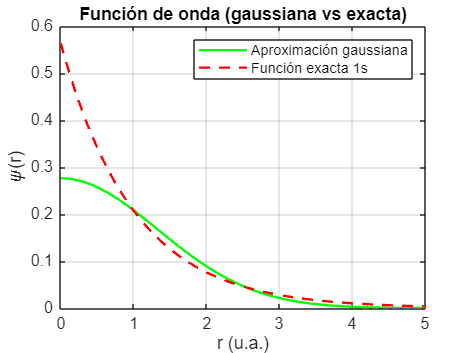


% ==================== VISUALIZACIÓN Y RESULTADOS (gaussiana matricial) =========
hartree_to_eV = 27.2114;

% --- 1. Función de onda y distribución radial -------------------------------
r_vals    = linspace(0,5,400);
b_opt_num = double(b_opt_all(1));
A_num     = double(subs(A(1), b, b_opt_num));
psi_vals  = A_num .* exp(-b_opt_num * r_vals.^2);
prob_vals = psi_vals.^2;

% Nueva: distribución radial P(r) = 4*pi*r^2*prob_vals
dist_rad = 4*pi .* r_vals.^2 .* prob_vals;

% Función exacta del hidrógeno (1s)
psi_exact = 1/sqrt(pi) * exp(-r_vals);
prob_exact = psi_exact.^2;
dist_rad_exact = 4*pi .* r_vals.^2 .* prob_exact;

% Gráfica de la función de onda
figure;
plot(r_vals, psi_vals, 'g', 'LineWidth', 1.5);
hold on;
plot(r_vals, psi_exact, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('r (u.a.)'); ylabel('\psi(r)');
title('Función de onda (gaussiana vs exacta)');
legend('Aproximación gaussiana', 'Función exacta 1s');
grid on;

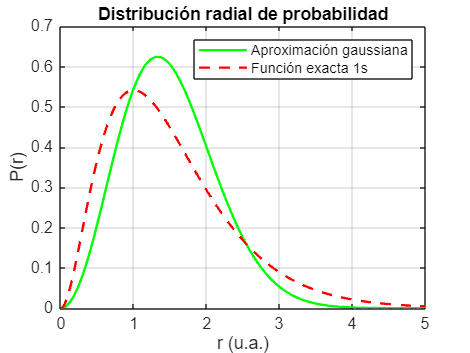


% Gráfica de la distribución radial (más significativa)
figure;
plot(r_vals, dist_rad, 'g', 'LineWidth', 1.5);
hold on;
plot(r_vals, dist_rad_exact, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('r (u.a.)'); ylabel('P(r)');
title('Distribución radial de probabilidad');
legend('Aproximación gaussiana', 'Función exacta 1s');
grid on;

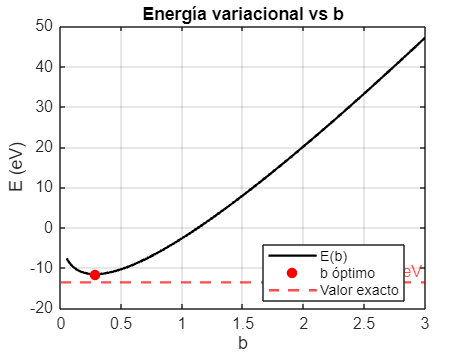

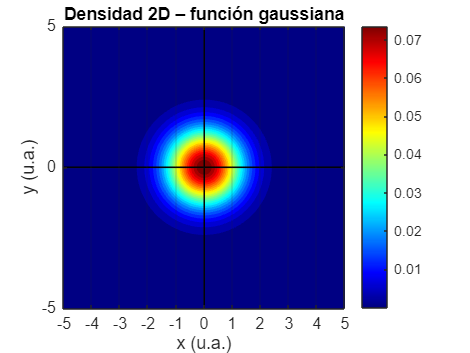



% --- 2. Energía vs b --------------------------------------------------------
b_scan    = linspace(0.05, 3, 250);
E_scan_eV = arrayfun(@(bb) double(subs(Energies(1), b, bb)) * hartree_to_eV, b_scan);
E_exact_eV = -13.6;  % energía exacta en eV

figure;
plot(b_scan, E_scan_eV, 'k', 'LineWidth', 1.5); hold on;
plot(b_opt_num, E_opt_eV(1), 'ro', 'MarkerFaceColor', 'r');
yline(E_exact_eV, 'r--', 'Exacta = -13.6 eV', 'LineWidth', 1.5);
hold off;
xlabel('b'); ylabel('E (eV)');
title('Energía variacional vs b');
legend({'E(b)', 'b óptimo', 'Valor exacto'}, 'Location','best');
grid on;


% --- 4. Pantalla de resultados ----------------------------------------------
E_opt_H      = E_opt(1);
E_opt_eV_num = E_opt_eV(1);

fprintf('\n==================== RESULTADOS ====================\n');


==================== RESULTADOS ====================


fprintf('b óptimo                 : %.4f\n', b_opt_num);

b óptimo                 : 0.2829


fprintf('Energía (Hartree)        : %.4f\n', E_opt_H);

Energía (Hartree)        : -0.4244


fprintf('Energía (eV)             : %.4f\n', E_opt_eV_num);

Energía (eV)             : -11.5489



% Errores
err_abs = abs(E_opt_eV_num - E_exact_eV);
err_rel = err_abs / abs(E_exact_eV) * 100;
fprintf('Valor exacto             : %.4f eV\n', E_exact_eV);

Valor exacto             : -13.6000 eV


fprintf('Error absoluto           : %.4f eV\n', err_abs);

Error absoluto           : 2.0511 eV


fprintf('Error relativo           : %.2f %%\n', err_rel);

Error relativo           : 15.08 %


### 1.3 MÉTODO NUMÉRICO DIRECTO (como validación inical del método)

% === Definir la función de energía que será minimizada ===
fprintf('--- MÉTODO VARIACIONAL NUMÉRICO PARA EL ÁTOMO DE HIDRÓGENO ---\n\n');

--- MÉTODO VARIACIONAL PARA EL ÁTOMO DE HIDRÓGENO ---



fprintf('Buscando el valor óptimo del parámetro b...\n');

Buscando el valor óptimo del parámetro b...



% === Configurar opciones de minimización ===
options = optimset('Display', 'iter', 'TolX', 1e-6);

% === Ejecutar la minimización ===
[b_opt, E_min] = fminbnd(@calculate_energy, 0.01, 2, options);

b = 0.7701, E = -0.2452 Hartree (T=1.1552, V_en=-1.4004)
 
 Func-count     x          f(x)         Procedure
    1       0.770112    -0.245215        initial
b = 1.2399, E = 0.0829 Hartree (T=1.8598, V_en=-1.7769)
    2        1.23989    0.0829387        golden
b = 0.4798, E = -0.3857 Hartree (T=0.7197, V_en=-1.1053)
    3       0.479775     -0.38566        golden
b = 0.3003, E = -0.4240 Hartree (T=0.4505, V_en=-0.8745)
    4       0.300337    -0.424024        golden
b = 0.2040, E = -0.4148 Hartree (T=0.3060, V_en=-0.7208)
    5       0.204005    -0.414752        parabolic
b = 0.2950, E = -0.4242 Hartree (T=0.4425, V_en=-0.8667)
    6       0.294974    -0.424225        parabolic
b = 0.2849, E = -0.4244 Hartree (T=0.4273, V_en=-0.8518)
    7       0.284896    -0.424408        parabolic
b = 0.2827, E = -0.4244 Hartree (T=0.4241, V_en=-0.8485)
    8       0.282709    -0.424413        parabolic
b = 0.2829, E = -0.4244 Hartree (T=0.4244, V_en=-0.8488)
    9       0.282924    -0.424413      


% === Calcular todos los componentes con el valor óptimo ===
[E_min, T_total, V_en_total] = calculate_energy(b_opt);

b = 0.2829, E = -0.4244 Hartree (T=0.4244, V_en=-0.8488)



% === Mostrar resultados finales ===
fprintf('\n=== RESULTADOS FINALES ===\n');


=== RESULTADOS FINALES ===


fprintf('Valor óptimo de b: %.4f\n', b_opt);

Valor óptimo de b: 0.2829


fprintf('Término cinético total T: %.4f\n', T_total);

Término cinético total T: 0.4244


fprintf('Término potencial electrón-núcleo total V_en: %.4f\n', V_en_total);

Término potencial electrón-núcleo total V_en: -0.8488


fprintf('Energía total <H>: %.4f Hartree\n', E_min);

Energía total <H>: -0.4244 Hartree


fprintf('Energía total <H>: %.4f eV\n', E_min * 27.2114);

Energía total <H>: -11.5489 eV



E_exact_eV = -13.6; % eV, energía conocida del hidrógeno
error_absoluto = abs((E_min * 27.2114) - E_exact_eV);
error_relativo = (error_absoluto / abs(E_exact_eV)) * 100;

fprintf('Valor experimental conocido: %.4f eV\n', E_exact_eV);

Valor experimental conocido: -13.6000 eV


fprintf('Error absoluto: %.4f eV\n', error_absoluto);

Error absoluto: 2.0511 eV


fprintf('Error relativo: %.2f%%\n\n', error_relativo);

Error relativo: 15.08%



## **2. FUNCIÓN HIDROGENOIDE **

###  2.1 MÉTODO DE VARIACIONES LINEALES (Parámetro Z ajustable)

clc; clear;
syms Z r positive
assumeAlso(Z > 0 & r > 0)

fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---\n\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---




% === Paso 1: Definir funciones base sin normalizar ===
f_base{1} = exp(-Z * r);  % Función hidrogenoide sin normalizar

n = length(f_base);  % Número de funciones base

% === Paso 2: Normalización de funciones base ===
f_norm = cell(1, n);       % Inicializamos funciones normalizadas
A = sym('A', [1 n]);       % Constantes de normalización

fprintf('--- Paso 1: Normalización de las funciones base ---\n');

--- Paso 1: Normalización de las funciones base ---


for i = 1:n
    norm_i = int(f_base{i}^2 * r^2 * 4*pi, r, 0, inf);
    norm_i = simplify(norm_i);
    A(i) = simplify(1 / sqrt(norm_i));
    f_norm{i} = simplify(A(i) * f_base{i});
    
    fprintf('\nFunción base %d sin normalizar:\n', i); disp(f_base{i});
    fprintf('Constante A_%d:\n', i); disp(A(i));
    fprintf('Función base normalizada ψ_%d(r):\n', i); disp(f_norm{i});
end


Función base 1 sin normalizar:


$${\mathrm{e}}^{-Z\,r}$$

Constante A_1:


$$\frac{Z^{3/2}}{\sqrt{\pi }}$$

Función base normalizada ψ_1(r):


$$\frac{Z^{3/2}\,{\mathrm{e}}^{-Z\,r}}{\sqrt{\pi }}$$


% === Paso 3: Matriz de solapamiento S_ij ===
fprintf('\n--- Paso 2: Matriz de solapamiento S ---\n');


--- Paso 2: Matriz de solapamiento S ---


S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        integrand_S = f_norm{i} * f_norm{j} * r^2 * 4*pi;
        S(i,j) = simplify(int(integrand_S, r, 0, inf));
        fprintf('S(%d,%d):\n', i, j); disp(S(i,j));
    end
end

S(1,1):


$$1$$


% === Paso 4: Matriz Hamiltoniana H_ij ===
fprintf('\n--- Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ---\n');


--- Paso 3: Matriz Hamiltoniana H = T + V_en + V_ee ---


H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        % Término cinético
        dfj = diff(f_norm{j}, r);
        d2fj = diff(dfj, r);
        laplacian_fj = d2fj + (2/r)*dfj;
        T = int(f_norm{i} * (-0.5 * laplacian_fj) * r^2 * 4*pi, r, 0, inf);
        fprintf('\nTérmino cinético T(%d,%d):\n', i, j); disp(T);
        
        % Término potencial electrón-núcleo V = -1/r
        V_en = -1/r;
        potential_en = f_norm{i} * f_norm{j} * V_en;
        V = simplify(int(potential_en * r^2 * 4*pi, r, 0, inf));
        fprintf('Término potencial electrón-núcleo V_en(%d,%d):\n', i, j); disp(V);

        % Término e-e (aquí 0, pero mantenemos estructura)
        V_ee = 0;
        fprintf('Término potencial electrón-electrón V_ee(%d,%d):\n', i, j); disp(V_ee);

        H(i,j) = simplify(T + V + V_ee);
        fprintf('H = T + V_en + V_ee:\n'); disp(H(i,j));
    end
end


Término cinético T(1,1):


$$\frac{Z^{2}}{2}$$

Término potencial electrón-núcleo V_en(1,1):


$$-Z$$

Término potencial electrón-electrón V_ee(1,1):
     0



H = T + V_en + V_ee:


$$\frac{Z\,\left(Z-2\right)}{2}$$


% === Paso 5: Solución general del problema de autovalores H c = E S c === 
fprintf('\n--- Paso 5: Solución del problema generalizado H c = E S c ---\n');


--- Paso 5: Solución del problema generalizado H c = E S c ---


syms E
eqn = det(H - E*S) == 0;
Energies = solve(eqn, E);  % Solucionamos las energías como expresión simbólica
Energies = simplify(Energies);

fprintf('Energías simbólicas obtenidas:\n');

Energías simbólicas obtenidas:


disp(Energies);

$$\frac{Z\,\left(Z-2\right)}{2}$$


% === Paso 6: Derivar cada energía respecto a Z y encontrar mínimo ===
fprintf('\n--- Paso 6: Derivadas de las energías respecto a Z y óptimos ---\n');


--- Paso 6: Derivadas de las energías respecto a Z y óptimos ---


E_opt = sym(zeros(size(Energies)));
E_opt_eV = zeros(size(Energies));
Z_opt_all = sym(zeros(size(Energies)));

for k = 1:length(Energies)
    fprintf('\n>> Energía E_%d:\n', k);
    E_k = Energies(k);
    dE_k = simplify(diff(E_k, Z));
    fprintf('Derivada dE/dZ:\n'); disp(dE_k);

    Z_sol = solve(dE_k == 0, Z);
    Z_sol = simplify(Z_sol(Z_sol > 0));  % Solo soluciones físicas positivas
    Z_opt_all(k) = Z_sol;


    E_opt_k = simplify(subs(E_k, Z, Z_sol));
    E_opt(k) = E_opt_k;

    E_eV_k = simplify(E_opt_k * 27.2114);
    E_opt_eV(k) = double(E_eV_k);

end


>> Energía E_1:


Derivada dE/dZ:


$$Z-1$$

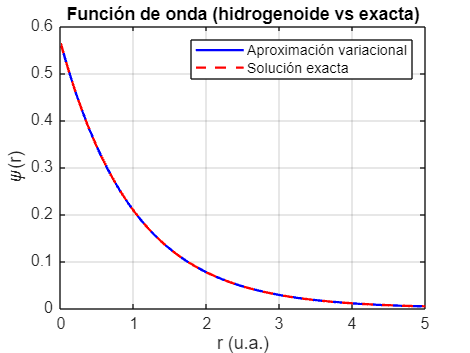


% === Paso final: Gráficas para todas las funciones base ===
% ==================== VISUALIZACIÓN Y RESULTADOS (hidrogenoide) ==============
hartree_to_eV = 27.2114;

% --- 1. Función de onda y distribución radial --------------------------------
r_vals     = linspace(0,5,400);
Z_opt_num  = double(Z_opt_all(1));
A_num      = double(subs(A(1), Z, Z_opt_num));
psi_vals   = A_num .* exp(-Z_opt_num .* r_vals);
prob_vals  = psi_vals.^2;

% Función exacta del hidrógeno (1s)
psi_exact = 1/sqrt(pi) * exp(-r_vals);
prob_exact = psi_exact.^2;

% Nueva: distribución radial P(r) = 4*pi*r^2*prob_vals
dist_rad   = 4*pi .* r_vals.^2 .* prob_vals;
dist_rad_exact = 4*pi .* r_vals.^2 .* prob_exact;

% Gráfica de la función de onda
figure;
plot(r_vals, psi_vals, 'b', 'LineWidth', 1.5);
hold on;
plot(r_vals, psi_exact, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('r (u.a.)'); ylabel('\psi(r)');
title('Función de onda (hidrogenoide vs exacta)');
legend('Aproximación variacional', 'Solución exacta');
grid on;

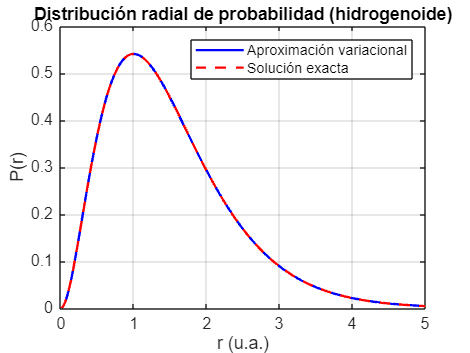


% Gráfica de la distribución radial (más significativa)
figure;
plot(r_vals, dist_rad, 'b', 'LineWidth', 1.5);
hold on;
plot(r_vals, dist_rad_exact, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('r (u.a.)'); ylabel('P(r)');
title('Distribución radial de probabilidad (hidrogenoide)');
legend('Aproximación variacional', 'Solución exacta');
grid on;

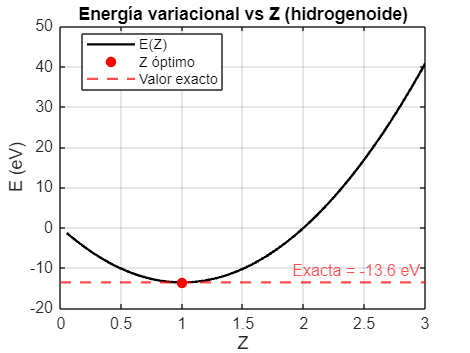



% --- 2. Energía variacional vs Z ---------------------------------------------
Z_scan     = linspace(0.05,3,250);
E_scan_eV  = arrayfun(@(Ztmp) double(subs(Energies(1), Z, Ztmp)) * hartree_to_eV, Z_scan);
E_exact_eV = -13.6;  % energía exacta en eV

figure;
plot(Z_scan, E_scan_eV, 'k', 'LineWidth', 1.5); hold on;
plot(Z_opt_num, E_opt_eV(1), 'ro', 'MarkerFaceColor', 'r');
yline(E_exact_eV, 'r--', 'Exacta = -13.6 eV', 'LineWidth', 1.5);
hold off;
xlabel('Z'); ylabel('E (eV)');
title('Energía variacional vs Z (hidrogenoide)');
legend('E(Z)', 'Z óptimo', 'Valor exacto', 'Location','best');
grid on;




% --- 4. Pantalla de resultados ------------------------------------------------
E_opt_H      = E_opt(1);          % Hartree
E_opt_eV_num = E_opt_eV(1);       % eV

fprintf('\n==================== RESULTADOS ====================\n');


==================== RESULTADOS ====================


fprintf('Z óptimo                 : %.4f\n', Z_opt_num);

Z óptimo                 : 1.0000


fprintf('Energía (Hartree)        : %.4f\n', E_opt_H);

Energía (Hartree)        : -0.5000


fprintf('Energía (eV)             : %.4f\n', E_opt_eV_num);

Energía (eV)             : -13.6057



E_exact_eV = -13.6;
err_abs = abs(E_opt_eV_num - E_exact_eV);
err_rel = err_abs/abs(E_exact_eV)*100;
fprintf('Valor exacto experimental: %.4f eV\n', E_exact_eV);

Valor exacto experimental: -13.6000 eV


fprintf('Error absoluto           : %.4f eV\n', err_abs);

Error absoluto           : 0.0057 eV


Error relativo           : 0.04 %


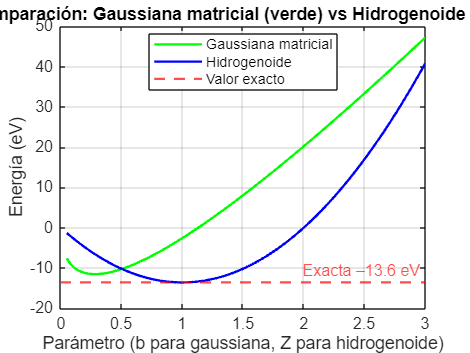

fprintf('Error relativo           : %.2f %%\n', err_rel);

## 3. ESTADOS EXCITADOS FUNCIONES HIDROGENOIDES

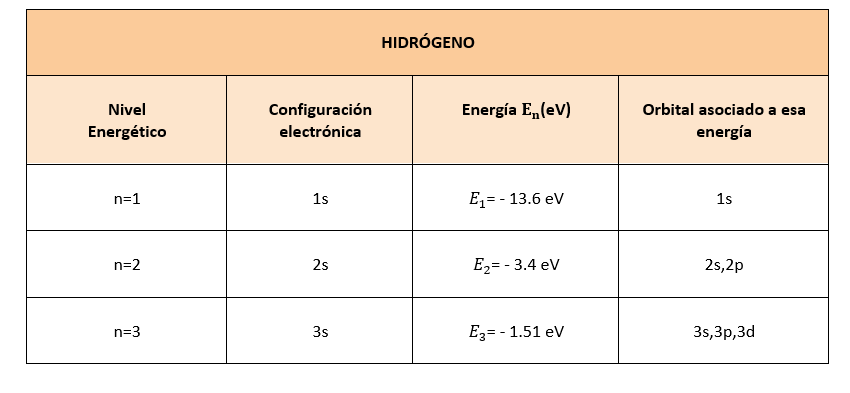

### 3.1 FUNCIONES HIDROGENOIDES COMPLETAS

clc; clear;
syms Z r theta phi positive
assumeAlso(Z > 0 & r > 0)
% === Solución del problema de autovalores generalizado ===
fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---


fprintf('--- INCLUYENDO ESTADOS EXCITADOS ---\n\n');

--- INCLUYENDO ESTADOS EXCITADOS ---





% === Definir funciones base sin normalizar ===
% Incluimos funciones para n=1, n=2 y n=3

% Armónicos esféricos de interés
Y00 = 1/sqrt(4*pi);
Y10 = sqrt(3/(4*pi)) * cos(theta);

% Funciones de onda completas
f_base{1} = 2*Z^(3/2) * exp(-Z*r) * Y00;                                 % 1s
f_base{2} = (Z^(3/2)/(2*sqrt(2))) * (2 - Z*r) .* exp(-Z*r/2) * Y00;      % 2s
f_base{3} = (4*Z^(3/2)/(81*sqrt(6))) * (6 - Z*r).*(Z*r) .* exp(-Z*r/3) * Y10;             % 3p



n = length(f_base);  % Número de funciones base

% === Normalización de funciones base (sin mostrar pasos intermedios) ===
f_norm = cell(1, n);       % Inicializamos funciones normalizadas
A = sym('A', [1 n]);       % Constantes de normalización

for i = 1:n
    if i == 3  % Para la función 2p necesitamos integrar sobre θ también
        norm_i = int(int(f_base{i}^2 * r^2 * sin(theta) * 2*pi, theta, 0, pi), r, 0, inf);
    else
        norm_i = int(f_base{i}^2 * r^2 * 4*pi, r, 0, inf);
    end
    norm_i = simplify(norm_i);
    A(i) = simplify(1 / sqrt(norm_i));
    f_norm{i} = simplify(A(i) * f_base{i});
end

% === Matriz de solapamiento S_ij (sin mostrar pasos intermedios) ===
S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        if i == 3 || j == 3  % Si alguna función es 2p
            if i == 3 && j == 3  % Si ambas son 2p
                integrand_S = f_norm{i} * f_norm{j} * r^2 * sin(theta) * 2*pi;
                S(i,j) = simplify(int(int(integrand_S, theta, 0, pi), r, 0, inf));
            else  % Si solo una es 2p, el producto es 0 por ortogonalidad angular
                S(i,j) = 0;
            end
        else  % Si ambas son funciones s
            integrand_S = f_norm{i} * f_norm{j} * r^2 * 4*pi;
            S(i,j) = simplify(int(integrand_S, r, 0, inf));
        end
    end
end

% === Matriz Hamiltoniana H_ij (sin mostrar pasos intermedios) ===
H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        % Si las funciones tienen diferente simetría angular, los elementos son 0
        if (i ~= 3 && j == 3) || (i == 3 && j ~= 3)
            H(i,j) = 0;
            continue;
        end
        
        % Término cinético
        if j == 3  % Para la función 2p
            % Laplaciano en coordenadas esféricas para la función 2p
            dfj_r = diff(f_norm{j}, r);
            d2fj_r = diff(dfj_r, r);
            laplacian_fj = d2fj_r + (2/r)*dfj_r - (2/r^2)*f_norm{j};  % Incluye término angular
            
            T_integrand = f_norm{i} * (-0.5 * laplacian_fj) * r^2 * sin(theta) * 2*pi;
            T = simplify(int(int(T_integrand, theta, 0, pi), r, 0, inf));
        else  % Para funciones s
            dfj = diff(f_norm{j}, r);
            d2fj = diff(dfj, r);
            laplacian_fj = d2fj + (2/r)*dfj;
            
            if i == 3  % Si i es 2p pero j es s
                T = 0;  % Por ortogonalidad angular
            else
                T_integrand = f_norm{i} * (-0.5 * laplacian_fj) * r^2 * 4*pi;
                T = simplify(int(T_integrand, r, 0, inf));
            end
        end
        
        % Término potencial electrón-núcleo V = -1/r
        V_en = -1/r;
        
        if (i == 3 || j == 3)  % Si alguna función es 2p
            if i == 3 && j == 3  % Si ambas son 2p
                V_integrand = f_norm{i} * f_norm{j} * V_en * r^2 * sin(theta) * 2*pi;
                V = simplify(int(int(V_integrand, theta, 0, pi), r, 0, inf));
            else  % Si solo una es 2p, el producto es 0 por ortogonalidad angular
                V = 0;
            end
        else  % Si ambas son funciones s
            V_integrand = f_norm{i} * f_norm{j} * V_en * r^2 * 4*pi;
            V = simplify(int(V_integrand, r, 0, inf));
        end

        H(i,j) = simplify(T + V);
    end
end


fprintf('Matriz de Solapamiento S:\n');

Matriz de Solapamiento S:


disp(S);

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$


fprintf('Matriz Hamiltoniana H:\n');

Matriz Hamiltoniana H:


disp(H);

$$\left(\begin{array}{ccc} \frac{Z\,\left(Z-2\right)}{2} & \frac{4\,\sqrt{2}\,Z\,\left(Z-1\right)}{27} & 0\\ \frac{4\,\sqrt{2}\,Z\,\left(Z-1\right)}{27} & \frac{Z\,\left(Z-2\right)}{8} & 0\\ 0 & 0 & \frac{Z\,\left(Z-2\right)}{18} \end{array}\right)$$


% Obtener expresiones simbólicas para cada energía
syms E
eqn = det(H - E*S) == 0;
Energies_sym = solve(eqn, E);
Energies_sym = simplify(Energies_sym);


% === Optimización del parámetro Z para cada estado ===
fprintf('\n--- Optimización del parámetro Z para cada estado ---\n');


--- Optimización del parámetro Z para cada estado ---



% Rango de valores de Z para búsqueda numérica
Z_range = linspace(0.5, 3, 100);

% Identificar los estados según las características de las expresiones simbólicas
% Evaluamos en Z=1 para identificar qué expresión corresponde a cada estado
E_vals_Z1 = double(subs(Energies_sym, Z, 1));
E_teoricos = [-0.5, -0.125, -0.055];  % Energías para n=1, n=2, n=2, n=3

% Asignar cada expresión al estado teórico más cercano
state_mapping = zeros(1, n);
for i = 1:n
    [~, idx] = min(abs(E_vals_Z1(i) - E_teoricos));
    state_mapping(i) = idx;
    % Marcar este estado teórico como asignado (valor muy grande)
    E_teoricos(idx) = 1e6;
end

% Reordenar según los estados físicos (1s, 2s, 2p, 3s)
[sorted_states, sort_idx] = sort(state_mapping);
E_sym_ordered = Energies_sym(sort_idx);

% Optimizar Z para cada estado
Z_opt = zeros(1, n);
E_opt = zeros(1, n);
estados = {'1', '2',  '3'};

for i = 1:n
    % Derivar la expresión de energía respecto a Z
    dE_dZ = diff(E_sym_ordered(i), Z);
    
    % Intentar resolver analíticamente
    Z_sol = solve(dE_dZ == 0, Z);
    Z_sol = Z_sol(imag(Z_sol) == 0);  % Solo soluciones reales
    Z_sol = Z_sol(Z_sol > 0);         % Solo soluciones físicas positivas
    
    if ~isempty(Z_sol)
        % Si hay solución analítica
        Z_opt(i) = double(Z_sol(1));
        E_opt(i) = double(subs(E_sym_ordered(i), Z, Z_opt(i)));
    else
        % Si no hay solución analítica, buscar numéricamente
        E_values = zeros(size(Z_range));
        for j = 1:length(Z_range)
            E_values(j) = double(subs(E_sym_ordered(i), Z, Z_range(j)));
        end
        [E_min, idx_min] = min(E_values);
        Z_opt(i) = Z_range(idx_min);
        E_opt(i) = E_min;
    end
    
    % Mostrar resultados
    fprintf('Nivel energético n= %s:\n', estados{i});
    fprintf('  Z óptimo: %.4f\n', Z_opt(i));
    fprintf('  Energía (Hartree): %.4f\n', E_opt(i));
    fprintf('  Energía (eV): %.4f eV\n', E_opt(i)*27.2114);
    
    % Comparar con el valor teórico
    if i == 1
        n_eff = 1;  % 1s
    elseif i == 2 
        n_eff = 2;  % 2s o 2p
    
    elseif  i == 3
        n_eff = 3;  % 3s
    end
    E_teorica = -0.5 / (n_eff^2);
    fprintf('  Energía teórica: %.4f Hartree (%.4f eV)\n', E_teorica, E_teorica*27.2114);
    fprintf('  Error relativo: %.4f%%\n',  abs((E_opt(i) - E_teorica)/E_teorica)*100);
    fprintf('  Error absoluto: %.4f%\n', abs(E_opt(i) - E_teorica));
end

Nivel energético n= 1:


  Z óptimo: 1.0000


  Energía (Hartree): -0.5000


  Energía (eV): -13.6057 eV


  Energía teórica: -0.5000 Hartree (-13.6057 eV)


  Error relativo: 0.0000%


  Error absoluto: 0.0000

Nivel energético n= 2:


  Z óptimo: 1.0000


  Energía (Hartree): -0.1250


  Energía (eV): -3.4014 eV


  Energía teórica: -0.1250 Hartree (-3.4014 eV)


  Error relativo: 0.0000%


  Error absoluto: 0.0000

Nivel energético n= 3:


  Z óptimo: 1.0000


  Energía (Hartree): -0.0556


  Energía (eV): -1.5117 eV


  Energía teórica: -0.0556 Hartree (-1.5117 eV)


  Error relativo: 0.0000%


  Error absoluto: 0.0000


% Calcular los coeficientes para cada estado con su Z óptimo
C_opt = cell(1, n);
for i = 1:n
    % Evaluar H y S con el Z óptimo
    H_num = double(subs(H, Z, Z_opt(i)));
    S_num = double(subs(S, Z, Z_opt(i)));
    
    % Resolver el problema de autovalores
    [V, D] = eig(H_num, S_num);
    E_vals = diag(D);
    
    % Encontrar el autovector correspondiente a la energía más cercana a E_opt(i)
    [~, idx] = min(abs(E_vals - E_opt(i)));
    c_i = V(:, idx);
    
    % Normalizar
    c_i = c_i / norm(c_i);
    C_opt{i} = c_i;
    
    fprintf('\nCoeficientes para el nivel energético n= %s (Z=%.4f):\n', estados{i}, Z_opt(i));
    for j = 1:n
        fprintf('  c%d = %.4f\n', j, c_i(j));
    end
end


Coeficientes para el nivel energético n= 1 (Z=1.0000):


  c1 = 1.0000
  c2 = 0.0000
  c3 = 0.0000



Coeficientes para el nivel energético n= 2 (Z=1.0000):


  c1 = 0.0000
  c2 = 1.0000
  c3 = 0.0000



Coeficientes para el nivel energético n= 3 (Z=1.0000):


  c1 = 0.0000
  c2 = 0.0000
  c3 = 1.0000


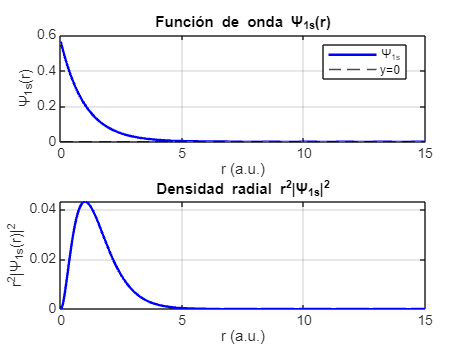

%% Preparación (idéntico para los tres estados)
if ~iscell(f_norm)
    f_norm = num2cell(f_norm);
end
phi_fun = cell(1,3);
for i = 1:3
    phi_fun{i} = matlabFunction(f_norm{i}, 'Vars', [r, theta, Z]);
end

r_vals = linspace(0,20,500);
theta0 = 0;
Psi   = zeros(3, numel(r_vals));
Dens  = zeros(3, numel(r_vals));
for k = 1:3
    psi_k = zeros(size(r_vals));
    for i = 1:3
        phi_ik = phi_fun{i}(r_vals, theta0, Z_opt(k));
        psi_k = psi_k + C_opt{k}(i)*phi_ik;
    end
    Psi(k,:)  = psi_k;
    Dens(k,:) = r_vals.^2 .* psi_k.^2;
end

r_lim = [0 15];
colors = {'b','m','r'};
labels = {'1s','2s','3p'};

%% Estado 1s
figure; set(gcf,'Name','Estado 1s','NumberTitle','off');
subplot(2,1,1);
plot(r_vals, Psi(1,:), 'Color', colors{1}, 'LineWidth',1.5); hold on;
yline(0,'k--','LineWidth',1); hold off;
xlabel('r (a.u.)'); ylabel('\Psi_{1s}(r)');
title('Función de onda \Psi_{1s}(r)');
legend('\Psi_{1s}','y=0','Location','Best'); grid on; xlim(r_lim);

subplot(2,1,2);
plot(r_vals, Dens(1,:), 'Color', colors{1}, 'LineWidth',1.5);
xlabel('r (a.u.)'); ylabel('r^2|\Psi_{1s}(r)|^2');
title('Densidad radial r^2|\Psi_{1s}|^2'); grid on; xlim(r_lim);

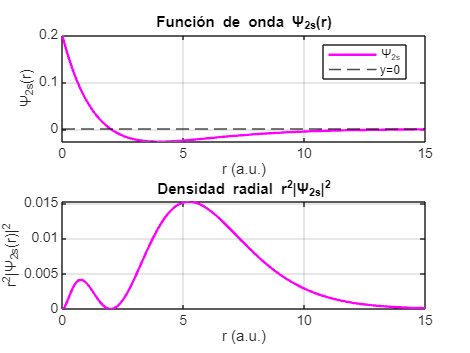



%% Estado 2s
figure; set(gcf,'Name','Estado 2s','NumberTitle','off');
subplot(2,1,1);
plot(r_vals, Psi(2,:), 'Color', colors{2}, 'LineWidth',1.5); hold on;
yline(0,'k--','LineWidth',1); hold off;
xlabel('r (a.u.)'); ylabel('\Psi_{2s}(r)');
title('Función de onda \Psi_{2s}(r)');
legend('\Psi_{2s}','y=0','Location','Best'); grid on; xlim(r_lim);

subplot(2,1,2);
plot(r_vals, Dens(2,:), 'Color', colors{2}, 'LineWidth',1.5);
xlabel('r (a.u.)'); ylabel('r^2|\Psi_{2s}(r)|^2');
title('Densidad radial r^2|\Psi_{2s}|^2'); grid on; xlim(r_lim);

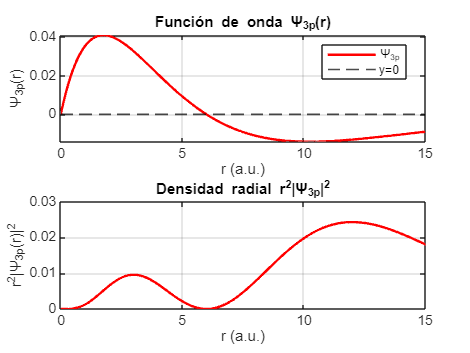



%% Estado 3p
figure; set(gcf,'Name','Estado 3p','NumberTitle','off');
subplot(2,1,1);
plot(r_vals, Psi(3,:), 'Color', colors{3}, 'LineWidth',1.5); hold on;
yline(0,'k--','LineWidth',1); hold off;
xlabel('r (a.u.)'); ylabel('\Psi_{3p}(r)');
title('Función de onda \Psi_{3p}(r)');
legend('\Psi_{3p}','y=0','Location','Best'); grid on; xlim(r_lim);

subplot(2,1,2);
plot(r_vals, Dens(3,:), 'Color', colors{3}, 'LineWidth',1.5);
xlabel('r (a.u.)'); ylabel('r^2|\Psi_{3p}(r)|^2');
title('Densidad radial r^2|\Psi_{3p}|^2'); grid on; xlim(r_lim);

### 3.1  FUNCIONES RADIALES HIDROGENOIDES 


clc; clear;
syms Z r theta phi positive
assumeAlso(Z > 0 & r > 0)
% === Solución del problema de autovalores generalizado ===
fprintf('--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---\n');

--- MÉTODO DE VARIACIONES LINEALES PARA EL ÁTOMO DE HIDRÓGENO ---


fprintf('--- INCLUYENDO ESTADOS EXCITADOS UTILIZANDO FUNCIONES RADIALES HIDROGENOIDES---\n\n');

--- INCLUYENDO ESTADOS EXCITADOS ---





% === Definir funciones base sin normalizar ===
% Incluimos funciones para n=1, n=2 y n=3

% Armónicos esféricos de interés
Y00 = 1/sqrt(4*pi);
% Funciones de onda completas
f_base{1} = 2*Z^(3/2) * exp(-Z*r) * Y00;                                 % 1s
f_base{2} = sqrt(Z^3/(8)) * (2-Z*r) * exp(-Z*r/2);
f_base{3} = (4*Z^(3/2)/(81*sqrt(6))) * (6 - Z*r).*(Z*r) .* exp(-Z*r/3);             % 3p


n = length(f_base);  % Número de funciones base

% === Normalización de funciones base (sin mostrar pasos intermedios) ===
f_norm = cell(1, n);       % Inicializamos funciones normalizadas
A = sym('A', [1 n]);       % Constantes de normalización

for i = 1:n
    if i == 3  % Para la función 2p necesitamos integrar sobre θ también
        norm_i = int(int(f_base{i}^2 * r^2 * sin(theta) * 2*pi, theta, 0, pi), r, 0, inf);
    else
        norm_i = int(f_base{i}^2 * r^2 * 4*pi, r, 0, inf);
    end
    norm_i = simplify(norm_i);
    A(i) = simplify(1 / sqrt(norm_i));
    f_norm{i} = simplify(A(i) * f_base{i});
end

% === Matriz de solapamiento S_ij (sin mostrar pasos intermedios) ===
S = sym(zeros(n));
for i = 1:n
    for j = 1:n
        if i == 3 || j == 3  % Si alguna función es 2p
            if i == 3 && j == 3  % Si ambas son 2p
                integrand_S = f_norm{i} * f_norm{j} * r^2 * sin(theta) * 2*pi;
                S(i,j) = simplify(int(int(integrand_S, theta, 0, pi), r, 0, inf));
            else  % Si solo una es 2p, el producto es 0 por ortogonalidad angular
                S(i,j) = 0;
            end
        else  % Si ambas son funciones s
            integrand_S = f_norm{i} * f_norm{j} * r^2 * 4*pi;
            S(i,j) = simplify(int(integrand_S, r, 0, inf));
        end
    end
end

% === Matriz Hamiltoniana H_ij (sin mostrar pasos intermedios) ===
H = sym(zeros(n));
for i = 1:n
    for j = 1:n
        % Si las funciones tienen diferente simetría angular, los elementos son 0
        if (i ~= 3 && j == 3) || (i == 3 && j ~= 3)
            H(i,j) = 0;
            continue;
        end
        
        % Término cinético
        if j == 3  % Para la función 2p
            % Laplaciano en coordenadas esféricas para la función 2p
            dfj_r = diff(f_norm{j}, r);
            d2fj_r = diff(dfj_r, r);
            laplacian_fj = d2fj_r + (2/r)*dfj_r - (2/r^2)*f_norm{j};  % Incluye término angular
            
            T_integrand = f_norm{i} * (-0.5 * laplacian_fj) * r^2 * sin(theta) * 2*pi;
            T = simplify(int(int(T_integrand, theta, 0, pi), r, 0, inf));
        else  % Para funciones s
            dfj = diff(f_norm{j}, r);
            d2fj = diff(dfj, r);
            laplacian_fj = d2fj + (2/r)*dfj;
            
            if i == 3  % Si i es 2p pero j es s
                T = 0;  % Por ortogonalidad angular
            else
                T_integrand = f_norm{i} * (-0.5 * laplacian_fj) * r^2 * 4*pi;
                T = simplify(int(T_integrand, r, 0, inf));
            end
        end
        
        % Término potencial electrón-núcleo V = -1/r
        V_en = -1/r;
        
        if (i == 3 || j == 3)  % Si alguna función es 2p
            if i == 3 && j == 3  % Si ambas son 2p
                V_integrand = f_norm{i} * f_norm{j} * V_en * r^2 * sin(theta) * 2*pi;
                V = simplify(int(int(V_integrand, theta, 0, pi), r, 0, inf));
            else  % Si solo una es 2p, el producto es 0 por ortogonalidad angular
                V = 0;
            end
        else  % Si ambas son funciones s
            V_integrand = f_norm{i} * f_norm{j} * V_en * r^2 * 4*pi;
            V = simplify(int(V_integrand, r, 0, inf));
        end

        H(i,j) = simplify(T + V);
    end
end


fprintf('Matriz de Solapamiento S:\n');

Matriz de Solapamiento S:


disp(S);

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$


fprintf('Matriz Hamiltoniana H:\n');

Matriz Hamiltoniana H:


disp(H);

$$\left(\begin{array}{ccc} \frac{Z\,\left(Z-2\right)}{2} & \frac{4\,\sqrt{2}\,Z\,\left(Z-1\right)}{27} & 0\\ \frac{4\,\sqrt{2}\,Z\,\left(Z-1\right)}{27} & \frac{Z\,\left(Z-2\right)}{8} & 0\\ 0 & 0 & \frac{Z\,\left(Z-2\right)}{18} \end{array}\right)$$


% Obtener expresiones simbólicas para cada energía
syms E
eqn = det(H - E*S) == 0;
Energies_sym = solve(eqn, E);
Energies_sym = simplify(Energies_sym);


% === Optimización del parámetro Z para cada estado ===
fprintf('\n--- Optimización del parámetro Z para cada estado ---\n');


--- Optimización del parámetro Z para cada estado ---



% Rango de valores de Z para búsqueda numérica
Z_range = linspace(0.5, 3, 100);

% Identificar los estados según las características de las expresiones simbólicas
% Evaluamos en Z=1 para identificar qué expresión corresponde a cada estado
E_vals_Z1 = double(subs(Energies_sym, Z, 1));
E_teoricos = [-0.5, -0.125, -0.055];  % Energías para n=1, n=2, n=2, n=3

% Asignar cada expresión al estado teórico más cercano
state_mapping = zeros(1, n);
for i = 1:n
    [~, idx] = min(abs(E_vals_Z1(i) - E_teoricos));
    state_mapping(i) = idx;
    % Marcar este estado teórico como asignado (valor muy grande)
    E_teoricos(idx) = 1e6;
end

% Reordenar según los estados físicos (1s, 2s, 2p, 3s)
[sorted_states, sort_idx] = sort(state_mapping);
E_sym_ordered = Energies_sym(sort_idx);

% Optimizar Z para cada estado
Z_opt = zeros(1, n);
E_opt = zeros(1, n);
estados = {'1', '2',  '3'};

for i = 1:n
    % Derivar la expresión de energía respecto a Z
    dE_dZ = diff(E_sym_ordered(i), Z);
    
    % Intentar resolver analíticamente
    Z_sol = solve(dE_dZ == 0, Z);
    Z_sol = Z_sol(imag(Z_sol) == 0);  % Solo soluciones reales
    Z_sol = Z_sol(Z_sol > 0);         % Solo soluciones físicas positivas
    
    if ~isempty(Z_sol)
        % Si hay solución analítica
        Z_opt(i) = double(Z_sol(1));
        E_opt(i) = double(subs(E_sym_ordered(i), Z, Z_opt(i)));
    else
        % Si no hay solución analítica, buscar numéricamente
        E_values = zeros(size(Z_range));
        for j = 1:length(Z_range)
            E_values(j) = double(subs(E_sym_ordered(i), Z, Z_range(j)));
        end
        [E_min, idx_min] = min(E_values);
        Z_opt(i) = Z_range(idx_min);
        E_opt(i) = E_min;
    end
    
    % Mostrar resultados
    fprintf('Nivel energético n= %s:\n', estados{i});
    fprintf('  Z óptimo: %.4f\n', Z_opt(i));
    fprintf('  Energía (Hartree): %.4f\n', E_opt(i));
    fprintf('  Energía (eV): %.4f eV\n', E_opt(i)*27.2114);
    
    % Comparar con el valor teórico
    if i == 1
        n_eff = 1;  % 1s
    elseif i == 2 
        n_eff = 2;  % 2s o 2p
    
    elseif  i == 3
        n_eff = 3;  % 3s
    end
    E_teorica = -0.5 / (n_eff^2);
    fprintf('  Energía teórica: %.4f Hartree (%.4f eV)\n', E_teorica, E_teorica*27.2114);
    fprintf('  Error relativo: %.4f%%\n',  abs((E_opt(i) - E_teorica)/E_teorica)*100);
    fprintf('  Error absoluto: %.4f%\n', abs(E_opt(i) - E_teorica));
end

Nivel energético n= 1:


  Z óptimo: 1.0000


  Energía (Hartree): -0.5000


  Energía (eV): -13.6057 eV


  Energía teórica: -0.5000 Hartree (-13.6057 eV)


  Error relativo: 0.0000%


  Error absoluto: 0.0000

Nivel energético n= 2:


  Z óptimo: 1.0000


  Energía (Hartree): -0.1250


  Energía (eV): -3.4014 eV


  Energía teórica: -0.1250 Hartree (-3.4014 eV)


  Error relativo: 0.0000%


  Error absoluto: 0.0000

Nivel energético n= 3:


  Z óptimo: 1.0000


  Energía (Hartree): -0.0556


  Energía (eV): -1.5117 eV


  Energía teórica: -0.0556 Hartree (-1.5117 eV)


  Error relativo: 0.0000%


  Error absoluto: 0.0000


% Calcular los coeficientes para cada estado con su Z óptimo
C_opt = cell(1, n);
for i = 1:n
    % Evaluar H y S con el Z óptimo
    H_num = double(subs(H, Z, Z_opt(i)));
    S_num = double(subs(S, Z, Z_opt(i)));
    
    % Resolver el problema de autovalores
    [V, D] = eig(H_num, S_num);
    E_vals = diag(D);
    
    % Encontrar el autovector correspondiente a la energía más cercana a E_opt(i)
    [~, idx] = min(abs(E_vals - E_opt(i)));
    c_i = V(:, idx);
    
    % Normalizar
    c_i = c_i / norm(c_i);
    C_opt{i} = c_i;
    
    fprintf('\nCoeficientes para el nivel energético n= %s (Z=%.4f):\n', estados{i}, Z_opt(i));
    for j = 1:n
        fprintf('  c%d = %.4f\n', j, c_i(j));
    end
end


Coeficientes para el nivel energético n= 1 (Z=1.0000):


  c1 = 1.0000
  c2 = 0.0000
  c3 = 0.0000



Coeficientes para el nivel energético n= 2 (Z=1.0000):


  c1 = 0.0000
  c2 = 1.0000
  c3 = 0.0000



Coeficientes para el nivel energético n= 3 (Z=1.0000):


  c1 = 0.0000
  c2 = 0.0000
  c3 = 1.0000


**Función para calcular la energía total  de forma numerica**

function [E, T_total, V_en_total] = calculate_energy(b_val)
% === Paso 1: Normalización de la función base ===
% Integral de |φ(r)|^2 * 4πr^2 dr desde 0 hasta infinito
norm_phi = integral(@(r) exp(-2 * b_val * r.^2) .* r.^2 .* 4 * pi, 0, Inf);
A = 1 / sqrt(norm_phi);


% === Paso 2: Cálculo del término cinético ===
% Para una gaussiana exp(-b*r^2), el Laplaciano es:
% ∇^2[exp(-b*r^2)] = (4b^2*r^2 - 6b) * exp(-b*r^2)
% El término cinético es -1/2 ∇^2
T_total = integral(@(r) A^2 .* (-0.5) .* (4 * b_val^2 * r.^2 - 6 * b_val) .* exp(-2 * b_val * r.^2) .* r.^2 .* 4 * pi, 0, Inf);

% === Paso 3: Término potencial electrón-núcleo V_en ===
% V_en = -1/r (Z=1 para hidrógeno)
V_en_total = integral(@(r) -1 * A^2 .* (1./r) .* exp(-2 * b_val * r.^2) .* r.^2 .* 4 * pi, 0, Inf);

% === Paso 4: Energía total ===
% E = ⟨φ|T|φ⟩ + ⟨φ|Ven|φ⟩
E = T_total + V_en_total;

% Mostrar progreso durante la minimización
fprintf('b = %.4f, E = %.4f Hartree (T=%.4f, V_en=%.4f)\n', ...
        b_val, E, T_total, V_en_total);
end

